# Taller 3: State Space Design 

## Magistal Control 

#### Eduardo Toro Bernal

#### Ingeniería Electrónica 

#### Universidad Nacional de Colombia

Se definen las matrices de la planta: 

Ap = [-184 -598 -810 0; 1 0 0 0; 0.2 0.2 0 0; 0 -0.2 1 0]

Ap =  -184.0000 -598.0000 -810.0000         0
    1.0000         0         0         0
    0.2000    0.2000         0         0
         0   -0.2000    1.0000         0


Bp = [5;0;0;0]

Bp =      5
     0
     0
     0


Cp = [0 -198 990 825]

Cp =      0  -198   990   825


n = length(Ap)

n = 4

## Punto 1

Encontrar la función de transferencia de u a y (lazo abierto). Encontrar los polos y ceros de lazo abierto. 

### Solución

La función de transferencia de lazo abierto es: 

syms s;
G = Cp*((s*eye(n)-Ap)^-1)*Bp

$$G = \frac{990\,\left(s+1\right)}{s^{3}+184\,s^{2}+760\,s+162}-\frac{990\,s}{s^{3}+184\,s^{2}+760\,s+162}+\frac{825}{s^{4}+184\,s^{3}+760\,s^{2}+162\,s}$$

Los polos de lazo abierto son: 

polos = eig(Ap)

polos =          0
 -179.7776
   -3.9970
   -0.2254


ceros = poles(1/G)

$$ceros = -\frac{5}{6}$$

## Punto 2

Diseñar un sistema de realimentación de estado que cumpla:

- Seguimiento asintótico de entradas tipo paso mediante la inclusión de un integrador. 

- El sistema de lazo cerrado NO debe presentar sobrepico. 

- La acción de control debe cumplir -5 < u(t) < 5 para referencias tipo escalón de amplitud 10. 

- El ancho de banda mínimo del sistema de lazo cerrado debe ser de 0.2 Hz. Dibujar el bode de lazo cerrado que va de r(t) a y(t).

### Solución

Se añade el modelo interno de un integrador: 

Ad = 0 

Ad = 0

Bd = 1

Bd = 1

Cd = 1

Cd = 1

m = length (Ad);

Se arma el sistema aumentado teniendo en cuenta los tamaños de las matrices: 

Abar = [Ap zeros(n,m); -Bd*Cp Ad]

Abar =  -184.0000 -598.0000 -810.0000         0         0
    1.0000         0         0         0         0
    0.2000    0.2000         0         0         0
         0   -0.2000    1.0000         0         0
         0  198.0000 -990.0000 -825.0000         0


Bbar = [Bp; zeros(m,1)]

Bbar =      5
     0
     0
     0
     0


Cbar = [Cp 0]

Cbar =      0  -198   990   825     0


Se ubican los polos en: 

pol = [-100 -1 -1 -1 -100]

pol =   -100    -1    -1    -1  -100


Se utiliza la formula de Ackerman para hallar k: 

k = acker(Abar,Bbar,pol);

Ac = Abar - Bbar*k

Ac = 1.0e+05 *

   -0.0020    0.2000   -1.5300   -0.9100    0.0006
    0.0000         0         0         0         0
    0.0000    0.0000         0         0         0
         0   -0.0000    0.0000         0         0
         0    0.0020   -0.0099   -0.0083         0


eig(Ac)

ans = -100.0000 + 0.0001i
-100.0000 - 0.0001i
  -1.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


Se separan los valores aumentados: 

ka = k(1:n); 
ki = k(n+1:n+m); 

La función de transferencia de lazo cerrado es: 

s = tf('s');
Go = Cbar*((s*eye(n+m)- Ac)^-1)*Bbar

Go =
 
                                                                                                                      
  990 s^12 + 4.028e05 s^11 + 6.213e07 s^10 + 4.374e09 s^9 + 1.273e11 s^8 + 7.576e11 s^7 + 2.111e12 s^6 + 3.344e12 s^5 
                                                                                                                      
                                                 + 3.209e12 s^4 + 1.855e12 s^3 + 5.973e11 s^2 + 8.25e10 s - 2.634e-05 
                                                                                                                      
  --------------------------------------------------------------------------------------------------------------------
                                                                                                                     
  s^15 + 609 s^14 + 1.554e05 s^13 + 2.137e07 s^12 + 1.685e09 s^11 + 7.423e10 s^10 + 1.596e12 s^9 + 1.129e13 s^8      
                                           

Se observa la respuesta al paso: 

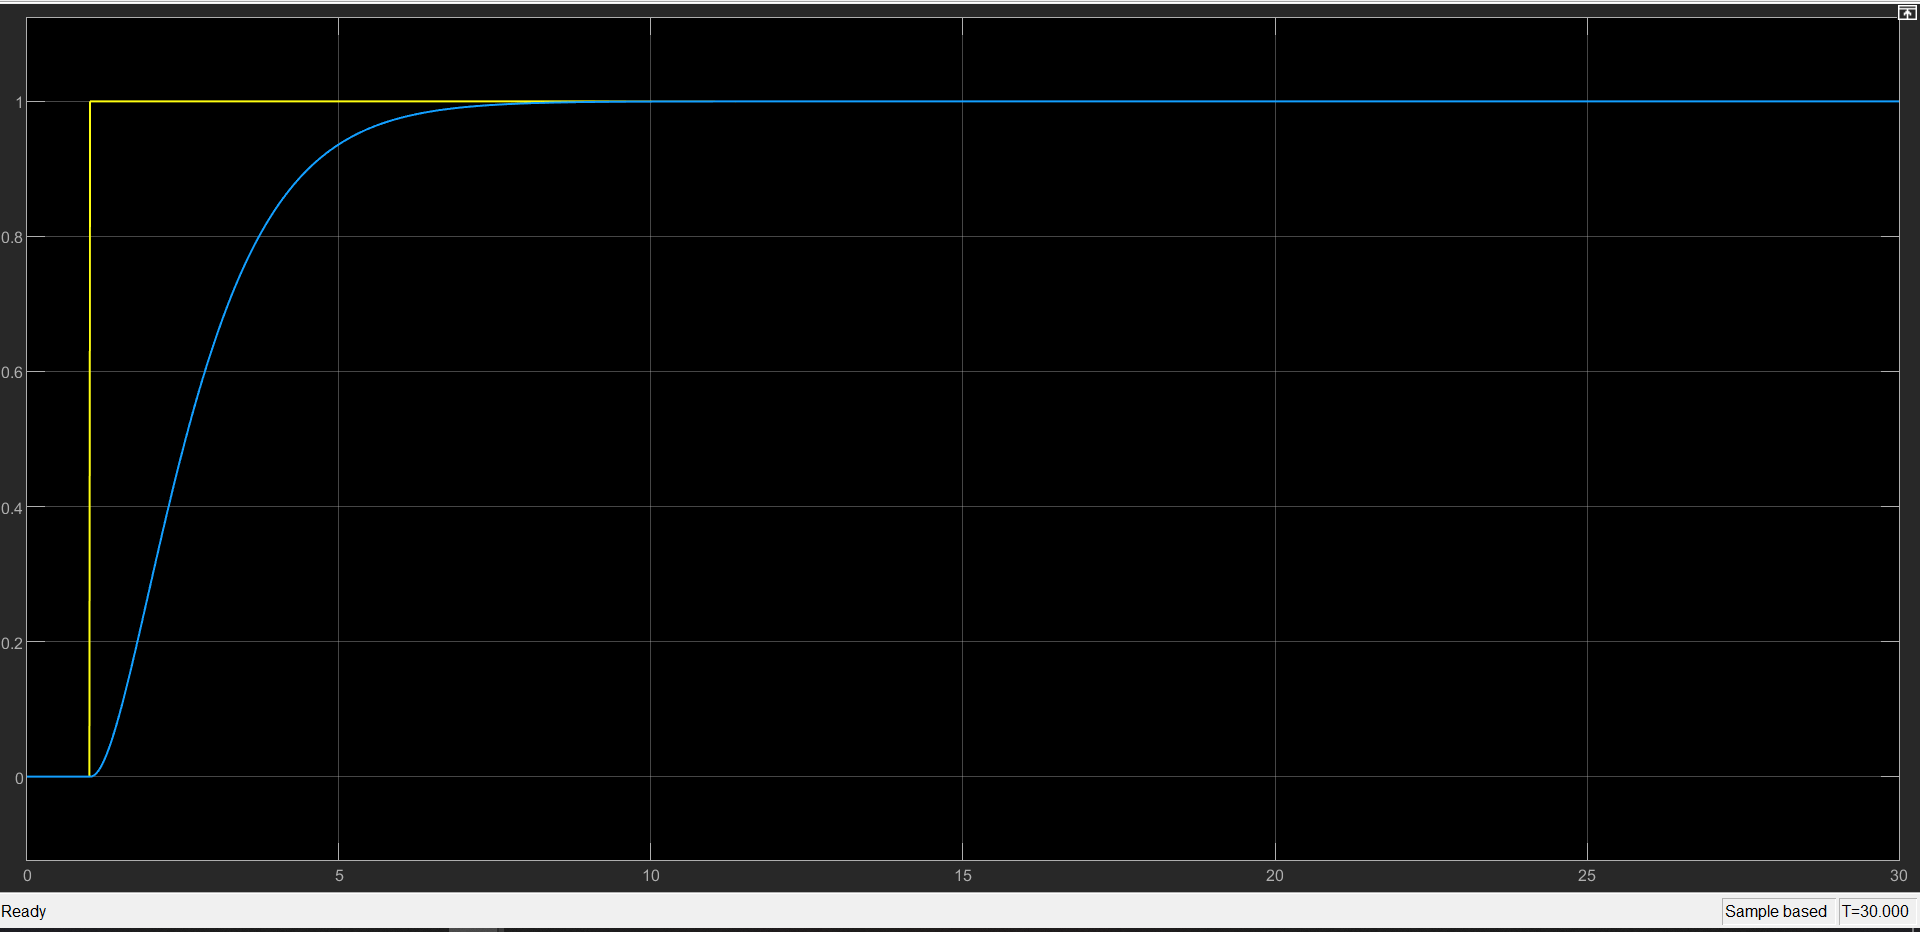

El ancho de banda se puede observar a continuación: 

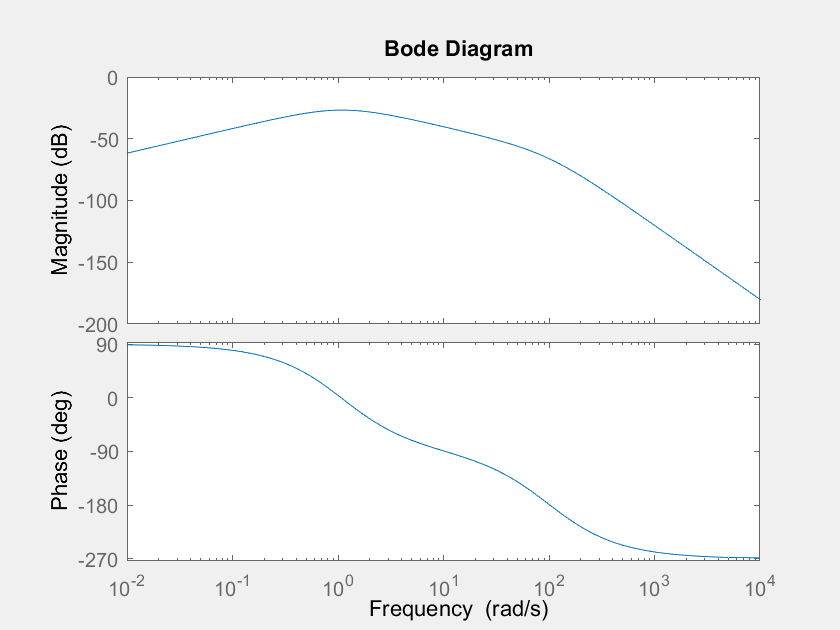

figure("Name", 'Ancho de banda'); 
set(gcf,'Visible', 'on');
bode(Go)

La acción de control es:

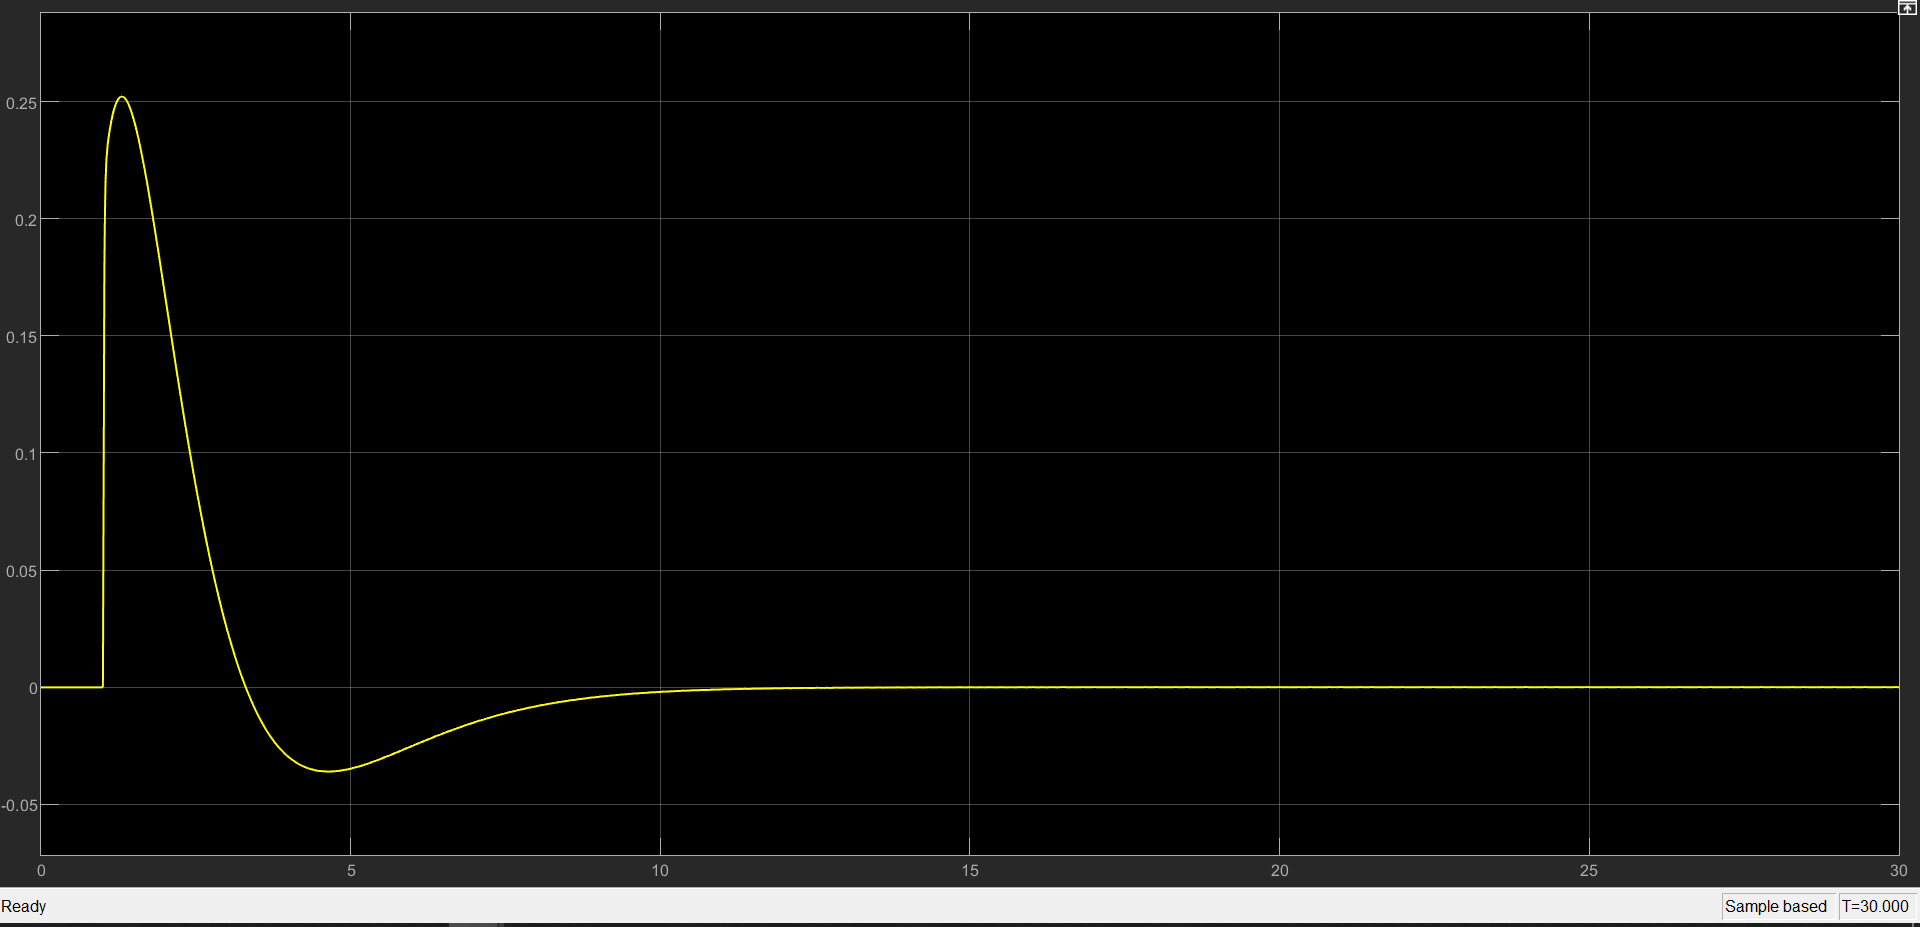

## Punto 3 

Diseñar un observador de estado para el sistema. 

### Solución

Se toman los polos de la realimentación 3 veces más rápidos que la de realimentación: 

pol1 = pol(1:4)

pol1 =   -100    -1    -1    -1


l = acker(Ap', Cp', 3*pol1)'

l = 1.0e+04 *

    1.9195
   -0.0107
   -0.0021
   -0.0000


## Punto 4

Encontrar las ecuaciones de estado del sistema de lazo cerrado (con observador y realimentación de estado). Encontrar la función de transferencia de lazo cerrado que va de r(t) a y(t). 

### Solución

Las ecuaciones de estado con observador y realimentación de estado están dadas por: 

A_obs = [Ap-Bp*ka Bp*ka; zeros(n) Ap-l*Cp]

A_obs = 1.0e+07 *

   -0.0000    0.0020   -0.0153   -0.0091    0.0000   -0.0021    0.0152    0.0091
    0.0000         0         0         0         0         0         0         0
    0.0000    0.0000         0         0         0         0         0         0
         0   -0.0000    0.0000         0         0         0         0         0
         0         0         0         0   -0.0000    0.3800   -1.9004   -1.5836
         0         0         0         0    0.0000   -0.0021    0.0106    0.0088
         0         0         0         0    0.0000   -0.0004    0.0021    0.0018
         0         0         0         0         0   -0.0000    0.0000    0.0000


B_obs = [Bp; zeros(n,m)]

B_obs =      5
     0
     0
     0
     0
     0
     0
     0


C_obs = [Cp zeros(1,n)]

C_obs =      0  -198   990   825     0     0     0     0


La función de transferencia de lazo cerrado de r(t) a y(t) es la misma que Go(s) ya que el observador es como si no existiera. 